# **RS-WISP-08-08: Safety Ellipse in CircumNavigation**

**WorkerInSpace**

**Hongseok Kim**

**2025/07/13**

## III. Phase 3: Walking Safety Ellipse Approach

### III.1 Generate WSE for single $r_{\textrm{LVLH}} ,v_{\textrm{LVLH}} ,n_{\textrm{target}}$


%% Input Parameters

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;


%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

% Timing of Docking
t_f = 10000;
N = 5;
alpha = 1;

[Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha);

mu = 398600.4415;
r_target_eci = r_target;
r_lvlh = delta_r_t_mat(1,:)';
v_lvlh = delta_v_t_mat(1,:)';
n_target_vehicle = sqrt(mu/norm(r_target_eci)^3);
x_0 = r_lvlh(1); y_0 = r_lvlh(2); z_0 = r_lvlh(3);
x_dot_0 = v_lvlh(1); y_dot_0 = v_lvlh(2); z_dot_0 = v_lvlh(3);

n = n_target_vehicle;

[x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n)

x_max = 22.4524

y_max = 44.9047

z_max = 19.9531

x_c = -2.0031e-04

y_c = -5.0717e-05

y_dot_c = 3.4761e-07

alpha = 5.8144

beta = 0

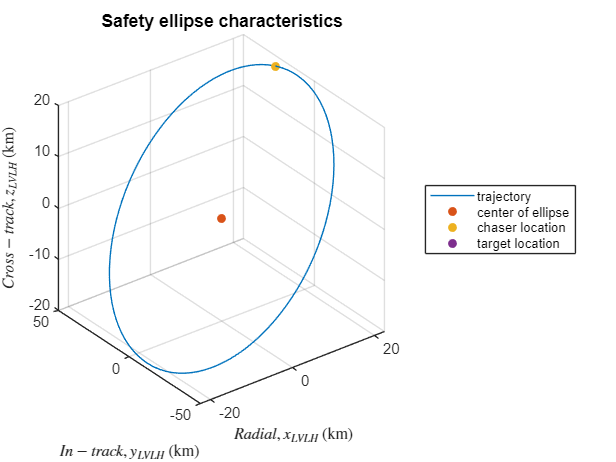


  % Option: Plot the safety ellipse
   figure;
   hold on
   grid on
   nt = linspace(0,2*pi);
   x_t = x_max * cos(nt + alpha) + x_c;
   y_t = -2 * x_max * sin(nt+alpha) + y_c;
   z_t = z_max * cos(nt + beta);

   plot3(x_t, y_t, z_t)
   scatter3(x_c,y_c,0,'filled') % Center of Ellipse
   scatter3(x_0, y_0, z_0,'filled') % Chaser Location
   scatter3(0,0,0,'filled') % Target Location

   xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
   ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
   zlabel('$Cross-track, z_{LVLH}$ (km)', 'Interpreter', 'latex')
   title('Safety ellipse characteristics','FontSize',12,'FontWeight','bold')
   axis('equal')
   view(3)
   legend('trajectory','center of ellipse','chaser location','target location','Location','eastoutside')

   % legend('trajectory','center of ellipse','chaser location','Ellipse Moving Direction','Location','northeast')


### III.2 Generate WSE for multiple periods

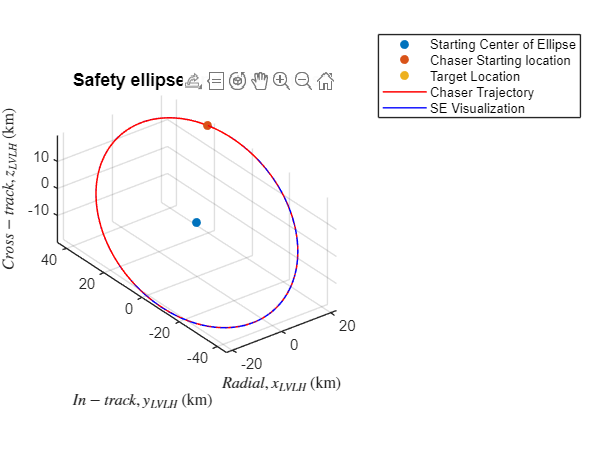

    number_of_periods = 3;

   figure;
   hold on
   grid on


   %nt = linspace(0,2*pi*number_of_periods);
   nt = 0:0.1:2*pi*number_of_periods;
   x_t = x_max * cos(nt + alpha) + x_c;
   y_t = -2 * x_max * sin(nt+alpha) + y_c + y_dot_c * nt/n;
   z_t = z_max * cos(nt + beta);
   chaser_trajectory_data = [x_t', y_t', z_t'];
   scatter3(x_c,y_c,0,'filled') % Center of Ellipse
   scatter3(x_0, y_0, z_0,'filled') % Chaser Location
   scatter3(0,0,0,'filled') % Target Location
   plot3(x_t,y_t,z_t,'red','LineWidth',1)
 
   for period_index = 1:number_of_periods+1
       nt_single = linspace(0,2*pi);
       x_t_single = x_max * cos(nt_single + alpha) + x_c;
       y_t_single = -2 * x_max * sin(nt_single+alpha) + y_c+ y_dot_c*(period_index-1)*2*pi/n;
       z_t_single = z_max * cos(nt_single + beta);
   plot3(x_t_single, y_t_single, z_t_single,'blue','LineWidth',1)
   end

   view(3)
   xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
   ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
   zlabel('$Cross-track, z_{LVLH}$ (km)', 'Interpreter', 'latex')
   title('Safety ellipse and trajectories','FontSize',12,'FontWeight','bold')
   legend('Starting Center of Ellipse', 'Chaser Starting location', 'Target Location','Chaser Trajectory','SE Visualization')
   axis('equal')

## III.3 Function for get safety ellipse parmeters

function [x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n)


  x_c = 4*x_0 + 2*y_dot_0/n;
  y_c = -2*x_dot_0/n+y_0;
  y_dot_c = -3*n/2*x_c;
  
  x_max = sqrt((x_dot_0/n)^2+(3*x_0 +2*y_dot_0/n)^2);
  y_max = 2 * x_max;
  z_max = sqrt((z_dot_0/n)^2+z_0^2);

  cos_alpha = -1/x_max * (3*x_0 +2*y_dot_0/n);
  sin_alpha = -1/x_max * (x_dot_0/n);

  if sin_alpha >= 0
    alpha = acos(cos_alpha);
  else
    alpha = 2*pi - acos(cos_alpha);
  end



  cos_beta = z_0/z_max;
  sin_beta = -1/z_max * z_dot_0/n;

  if sin_beta>=0
      beta = acos(cos_beta);
  else
      beta = 2*pi - acos(cos_beta);
  end

  if isnan(beta) == true
   beta = 0;
  end
end

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end



## Algorithm 3.4 Coordinate Transform between ECI and LVLH

function [r_lvlh, v_lvlh] = eci2lvlh(r_t_eci, v_t_eci, r_c_eci, v_c_eci, n)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_lvlh_eci = [i_hat'; j_hat'; k_hat'];

  r_lvlh = Q_lvlh_eci * (r_c_eci - r_t_eci);
  v_lvlh = Q_lvlh_eci * (v_c_eci - v_t_eci - n*cross(k_hat,r_c_eci - r_t_eci));

end




function [r_c_eci, v_c_eci] = lvlh2eci(r_t_eci, v_t_eci, r_lvlh, v_lvlh)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_eci_lvlh = [i_hat, j_hat, k_hat];

  r_c_eci = Q_eci_lvlh * r_lvlh + r_t_eci;
  v_c_eci = Q_eci_lvlh * v_lvlh + v_t_eci + n* cross(k_hat , r_c_eci - r_t_eci);

end

## Appeneix: CircumNavigation Algorithm

function [Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha)

r_0 = r_target;
v_0 = v_target;
r = r_chaser;
v = v_chaser;

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_LVLH_ECI = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_LVLH_ECI * delta_r;

% Relative velocity just before launch into the rendezvous trajectory is
delta_v_0_minus = Q_LVLH_ECI * delta_v;

tf = N * 2* pi / n;

delta_v_0_plus = [0, n/2, 0;
                  -2*n, 0, 0;
                  0, 0, 0] * delta_r_0;

% Delta-v at the beginning of the rendezvous maneuver
Delta_v_0 = delta_v_0_plus - delta_v_0_minus;


% Drawing Reference Chaser Trajector wrt Target
t_vector = linspace(0,tf);
delta_r_t_mat = zeros(length(t_vector),3);
delta_v_t_mat = zeros(length(t_vector),3);

for timestep = 1:length(t_vector)

    t = t_vector(timestep);

    nt = n*t;

    Phi_rr_t = [4 - 3*cos(nt),   0, 0;
              6*(sin(nt) - nt),1,0;
              0,0, cos(nt)];
    
    Phi_rv_t = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
              2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
              0,0,1/n*sin(nt)];
    
    Phi_vr_t = [3*n*sin(nt),0,0;
              6*n*(cos(nt)-1),0,0;
              0,0,-n*sin(nt)];
    Phi_vv_t = [cos(nt), 2*sin(nt),0
             -2*sin(nt), 4*cos(nt)-3, 0;
              0,0,cos(nt)];

    delta_r_t = Phi_rr_t * delta_r_0 + Phi_rv_t * delta_v_0_plus;
    delta_v_t = Phi_vr_t * delta_r_0 +  Phi_vv_t * delta_v_0_plus;

    delta_r_t_mat(timestep,:) = delta_r_t';
    delta_v_t_mat(timestep,:) = delta_v_t';
end

v_plus_ECI = v_0 + cross(Omega_target, delta_r) + inv(Q_LVLH_ECI) * delta_v_0_plus;

end